# SMSM Model

Single Machine to Single Machine Model, to model a weak grid with finite inertia. Based on Gomez's eqs 10.3-10.7 for both machines, grid is motoring, grid swing eq (5) may have additional damping term commented out. CURRENTLY NO DISTURBANCE/STEP-CHANGE, TBC.

### **Constants**

% Machine 1 / generator
D1  = 0.1;
H1  = 3;
Xd1 = 0.1;
XT1 = 0.05;
X1 = Xd1 + XT1;

% Machine 2 / finite grid
D2 = 4*D1;
H2 = 4*H1;    %Grid Inertia
Xd2 = 0.05;
XT2 = 0.05;
X2 = Xd2 + XT2;

% Network
XL = 0.3;
XTot = X1 + XL + X2;

f  = 50;
ws = 2*pi*f;  %chosen reference rotational velocity, rad/s

### Design Parameters

K1 = 1.2;  %Gen Gain Constant
K2 = 4*K1; %Grid Gain Constant

### Specified Inputs

Pm1 = 1.2;          %Generator mechanical power input
Pm2 = -Pm1;         %Grid is initially motoring at equilibrium

V1o = 1;            %Gen terminal votlage reference (extend to a step reference soon?)
V2o = 1;

%Comment out below to disable fault
V1o_init = 1;      %Desired V1, reference variable, initial reference
V1o_after = 1.07; %V1o STEP VARIATION
tstep = 5;            %V1o STEP VARIATION
V1o_step = @(t) V1o_init + (V1o_after - V1o_init).*(t >= tstep);

% % Check that a power-flow solution exists
% s1 = Pm*XL/(Vinf*V1o_init);
% s2 = Pm*XL/(Vinf*V1o_after);
% if abs(s1) > 1 && abs(s2) >1
%     error('No steady-state equilibrium exists for this Pm and V1o.');
% end

### Initial Conditions

%The following are for initial conditions at a steady state equilibrium
domega10 = 0;
domega20 = 0;
V1PCCmag0 = V1o;
V2PCCmag0 = V2o;
delta2PCC0 = 0;     %Set this then calculate following initial conditions at the equilibrium
delta1PCC0 = asin(Pm1*XL/(V1PCCmag0*V2PCCmag0));

Q12 = (V1PCCmag0^2 - V1PCCmag0*V2PCCmag0*cos(delta1PCC0-delta2PCC0))/XL;
Q21 = (V2PCCmag0^2 - V2PCCmag0*V1PCCmag0*cos(delta2PCC0-delta1PCC0))/XL;

E10 = hypot(Pm1*X1/V1PCCmag0, V1PCCmag0 + Q12*X1/V1PCCmag0);
delta10 = delta1PCC0 + atan2(Pm1*X1/V1PCCmag0, V1PCCmag0 + Q12*X1/V1PCCmag0);
E20 = hypot(Pm2*X2/V2PCCmag0, V2PCCmag0 + Q21*X2/V2PCCmag0);
delta20 = delta2PCC0 + atan2(Pm2*X2/V2PCCmag0, V2PCCmag0 + Q21*X2/V2PCCmag0);

x0 = [delta10; domega10; E10; delta20; domega20; E20; V1PCCmag0; delta1PCC0; V2PCCmag0; delta2PCC0];

### State Space Equations and Solve

DynamicsEqs = @(t,x)[ x(2);                                                                                %1
                      (ws/(2*H1))*(Pm1-(x(3)*x(6)/XTot)*sin(x(1)-x(4))-D1*x(2));                           %2
                      %comment out below if fault is enaled
                     %K1*(V1o - x(7));                                                                  %3
                      % comment out below if fault is disabled
                      K1*(V1o_step(t) - x(7));
                      x(5);                                                                                %4
                      (ws/(2*H2))*(Pm2+(x(3)*x(6)/XTot)*sin(x(1)-x(4))-D2*x(5));                           %5
% (ws/(2*H2))*(Pm2+(x(3)*x(6)/XTot)*sin(x(1)-x(4))-D2*x(5)-(D3*(x(4)-delta20))); %5 + potential extra damping term
                      K2*(V2o - x(9));                                                                  %6
                      (x(3)*x(7)/X1)*sin(x(1)-x(8))-(x(7)*x(9)/XL)*sin(x(8)-x(10));                        %7
                      (x(3)*x(7)*cos(x(1)-x(8))-x(7)^2)/X1-(x(7)^2-x(7)*x(9)*cos(x(8)-x(10)))/XL;          %8
                      (x(6)*x(9)/X2)*sin(x(4)-x(10))-(x(9)*x(7)/XL)*sin(x(10)-x(8));                       %9
                      (x(6)*x(9)*cos(x(4)-x(10))-x(9)^2)/X2-(x(9)^2-x(9)*x(7)*cos(x(10)-x(8)))/XL];        %10


Mass = diag([1 1 1 1 1 1 0 0 0 0]);
options = odeset('Mass', Mass);
tspan = [0 30];
[t,x] = ode15s(DynamicsEqs, tspan, x0, options);
%Now we've got x = [delta1, domega1, E1, delta2, domega2, E2, V1PCCmag, delta1PCC, V2PCCmag, delta2PCC], a vector with length depending on time. 

### Calculating PG and QG at each point in time

% Use x vector to get P, Q
delta1  = x(:,1);
domega1 = x(:,2);
E1      = x(:,3);
delta2  = x(:,4);
domega2 = x(:,5);
E2      = x(:,6);
V1PCCmag  = x(:,7);
delta1PCC = x(:,8);
V2PCCmag  = x(:,9);
delta2PCC = x(:,10);

PG      = zeros(length(t),1);
QG      = zeros(length(t),1);

for n = 1:length(t)
    
    PG(n) = (V1PCCmag(n)*V2PCCmag(n)/XL)*sin(delta1PCC(n)-delta2PCC(n)); % Active power from PCC1 to PCC2

    QG(n) = (V1PCCmag(n)^2/XL) - (V1PCCmag(n)*V2PCCmag(n)/XL)*cos(delta1PCC(n)-delta2PCC(n)); %Reactive power from PCC1 to PCC2
end

### Plot -WHICH PLOTS WE WANT TBC

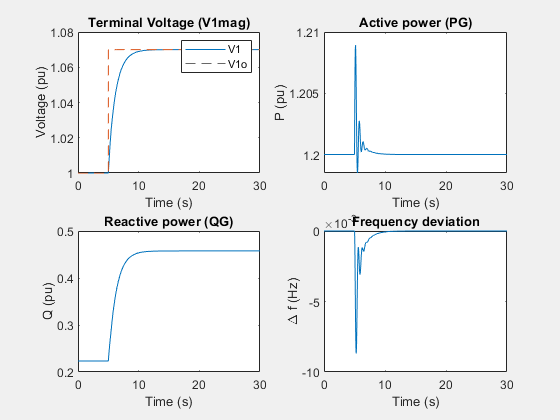

figure('Visible','on');
subplot(2,2,1)
plot(t, V1PCCmag); hold on;
yline(V1o, '--');
%comment out if fault is not enabled 
plot(t, V1o_step(t), '--');
xlabel('Time (s)');
ylabel('Voltage (pu)');
legend('V1', 'V1o');
title('Terminal Voltage (V1mag)');

subplot(2,2,2);
plot(t, PG);
xlabel('Time (s)');
ylabel('P (pu)');
title('Active power (PG)');

subplot(2,2,3);
plot(t, QG);
xlabel('Time (s)');
ylabel('Q (pu)');
title('Reactive power (QG)');

subplot(2,2,4);
plot(t, domega1/(2*pi));
xlabel('Time (s)');
ylabel('\Delta f (Hz)');
title('Frequency deviation');


%RoCoF -> use domega to get it, easy
